# LC Parser State Dynamics Example

*Peter beim Graben, Matthias Wolff*

BTU Cottbus-Senftenberg

fock.addFockBoxPaths();

We consider a left-corner parser processing the sentence "Frankie goes to Hollywood". Each time the parser generates one of the terminals {"Frankie", "goes", "to", "Hollywood"}, we realize the phrase structure tree built so far as a ket in a Fock space. We call such a ket a *parser state*. Fig. 1 shows the (partial) phrase structure trees in Chomsky normal form.

       ** Figure 1 - LC parser states**

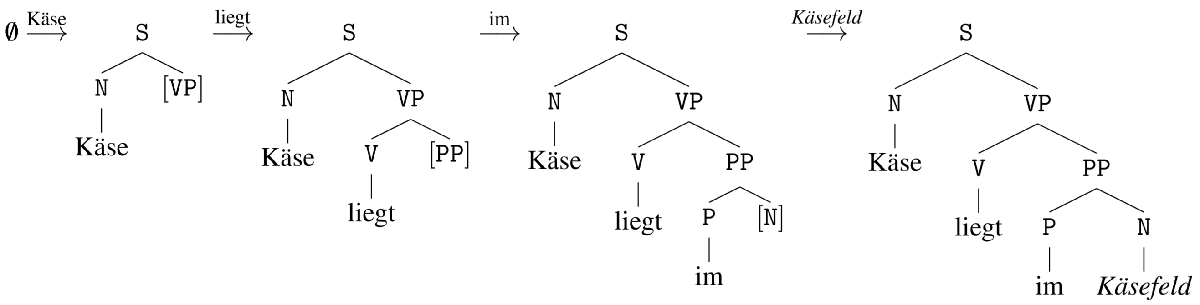

The kets representing the parser states in a Fock space are obtained by the constructor of the [`fockpst`](matlab:helpPopup fockpst) class as follows:

% Parser states over time
% - (Start)
pst{1} = fockpst({});
pst{1}.name  = "(start)";
disp(pst{1});

  fockobj

    Name: (start) 
    Type: ket 

    (^,ε)               	1.000000



% - Käse
pst{2} = fockpst(       ...
  {'S'                  ...
    {'N' 'Frankie'}     ...
    '[VP]'              ...
  });
pst{2}.name = 'Frankie';
disp(pst{2});

  fockobj

    Name: Frankie 
    Type: ket 

    (Frankie⊗/⊗/,ε)     	1.000000
    (N⊗^⊗/,ε)           	1.000000
    (S⊗^,ε)             	1.000000
    ([VP]⊗\,ε)          	1.000000



% - liegt
pst{3} = fockpst(       ...
  {'S'                  ...
    {'N' 'Frankie'}     ...
    {'VP'               ...
      {'V' 'goes'}      ...
      '[PP]'            ...
    }                   ...
  });
pst{3}.name = 'goes';
disp(pst{3});

  fockobj

    Name: goes 
    Type: ket 

    (Frankie⊗/⊗/,ε)     	1.000000
    (N⊗^⊗/,ε)           	1.000000
    (S⊗^,ε)             	1.000000
    (VP⊗^⊗\,ε)          	1.000000
    (V⊗^⊗/⊗\,ε)         	1.000000
    ([PP]⊗\⊗\,ε)        	1.000000
    (goes⊗/⊗/⊗\,ε)      	1.000000



% - im
pst{4} = fockpst(       ...
  {'S'                  ...
    {'N' 'Frankie'}     ...
    {'VP'               ...
      {'V' 'goes'}      ...
      {'PP'             ...
        {'P' 'to'}      ...
        '[N]'           ...
      }                 ...
    }                   ...
  });
pst{4}.name = 'to';
disp(pst{4});

  fockobj

    Name: to 
    Type: ket 

    (Frankie⊗/⊗/,ε)     	1.000000
    (N⊗^⊗/,ε)           	1.000000
    (PP⊗^⊗\⊗\,ε)        	1.000000
    (P⊗^⊗/⊗\⊗\,ε)       	1.000000
    (S⊗^,ε)             	1.000000
    (VP⊗^⊗\,ε)          	1.000000
    (V⊗^⊗/⊗\,ε)         	1.000000
    ([N]⊗\⊗\⊗\,ε)       	1.000000
    (goes⊗/⊗/⊗\,ε)      	1.000000
    (to⊗/⊗/⊗\⊗\,ε)      	1.000000



% - Käsefeld
pst{5} = fockpst(       ...
{ 'S'                   ...
  {'N' 'Frankie'}       ...
  {'VP'                 ...
    {'V' 'goes'}        ...
    {'PP'               ...
      {'P' 'to'}        ...
      {'N' 'Hollywood'} ...
    }                   ...
  }                     ...
});
pst{5}.name = 'Hollywood';
disp(pst{5});

  fockobj

    Name: Hollywood 
    Type: ket 

    (Frankie⊗/⊗/,ε)     	1.000000
    (Hollywood⊗/⊗\⊗\⊗\,ε)	1.000000
    (N⊗^⊗/,ε)           	1.000000
    (N⊗^⊗\⊗\⊗\,ε)       	1.000000
    (PP⊗^⊗\⊗\,ε)        	1.000000
    (P⊗^⊗/⊗\⊗\,ε)       	1.000000
    (S⊗^,ε)             	1.000000
    (VP⊗^⊗\,ε)          	1.000000
    (V⊗^⊗/⊗\,ε)         	1.000000
    (goes⊗/⊗/⊗\,ε)      	1.000000
    (to⊗/⊗/⊗\⊗\,ε)      	1.000000



% Get enclosing Fock sub-space basis
H = fockbasis(pst);
disp(H);

  fockbasis

    Dimensions: 16
    Sectors   : 6
    Type      : canonical

    ε                   	1
    Frankie⊗/⊗/         	2
    Hollywood⊗/⊗\⊗\⊗\   	3
    N⊗^⊗/               	4
    N⊗^⊗\⊗\⊗\           	5
    PP⊗^⊗\⊗\            	6
    P⊗^⊗/⊗\⊗\           	7
    S⊗^                 	8
    VP⊗^⊗\              	9
    V⊗^⊗/⊗\             	10
    [N]⊗\⊗\⊗\           	11
    [PP]⊗\⊗\            	12
    [VP]⊗\              	13
    ^                   	14
    goes⊗/⊗/⊗\          	15
    to⊗/⊗/⊗\⊗\          	16


The trajectory of the parser states is shown in Fig. 2.

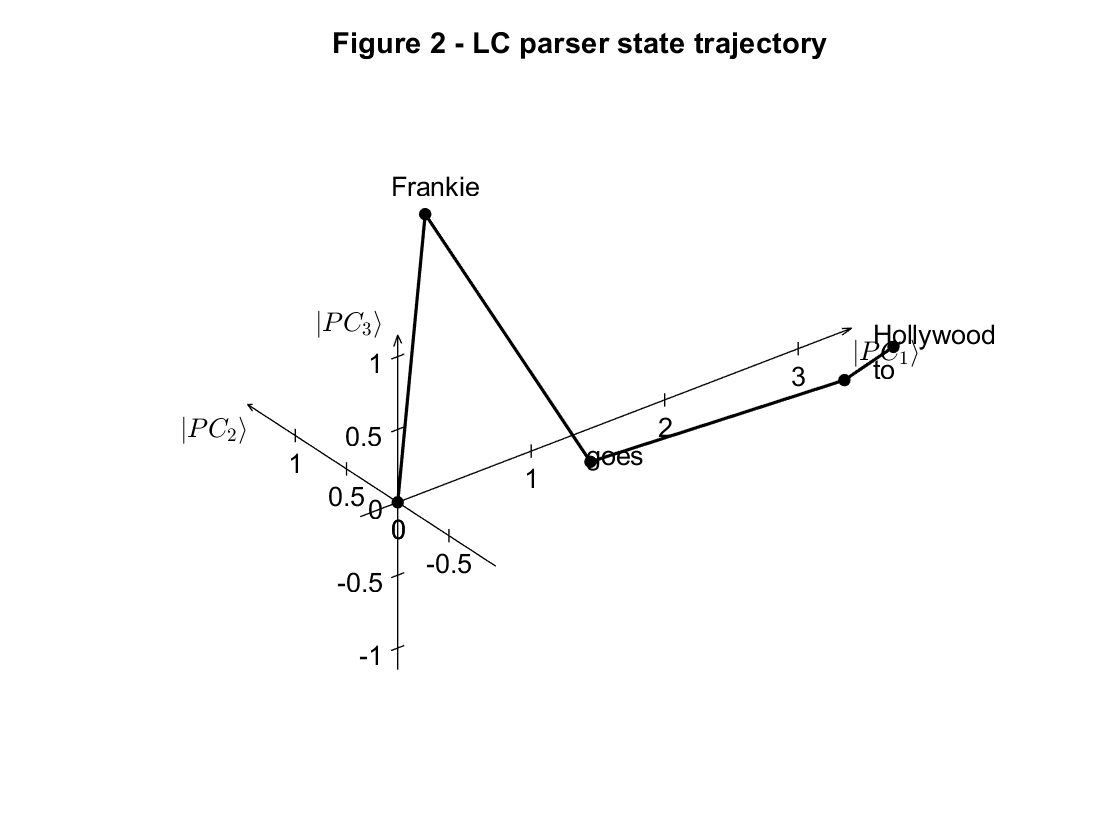

% Plot parser state trajectory
figure;
% NOTE: Projection turned off because transparency is not displayed in live editor. 
% -->
% [~,vv] = fock.plotVector(pst,'mode','trajectory','axesLocation','origin','projection','xy');
% <-->
[~,vv] = fock.plotVector(pst,'mode','trajectory','axesLocation','origin');
% <--
title('Figure 2 - LC parser state trajectory');

disp('Vectors plotted:');

Vectors plotted:


disp(vv);

         0         0         0
    1.1882    1.2802    0.9733
    2.2282    1.0224   -0.9733
    2.9903   -0.4636    0.0000
    3.1200   -0.7733    0.3244



## References

[1] P. beim Graben, M. Huber, R. Römer, I. Schmitt, M. Wolff: *Der Fockraum als Labyrinth: Wissensrepräsentation und Sprachverarbeitung am Beispiel des Mouse-Maze-Problems.* In A. Berton et al. (Hrsg.): Elektronische Sprachverarbeitung 2018, Tagungsband 29. Konferenz, TUDpress, S. 167-174, 2018. ISBN: 978-3-95908-128-3.